# **Matlab homework (lab 2)**

 clear; close all;
% insert your name here
Name{1} = 'Cinta Arnau Arasa';

% ALSO : Do not use make additional calls to "clear all;" between steps.

%% load file from .mat
%filename = 'LAB2';
%save(filename, 'Random');
D = load('datafile.mat') % you can edit here if your datafile has a different name, but do not add path to the file (otherwise it does not work on a different computer)

D = struct with fields:
    x1: [750×1 double]
    x2: [750×1 double]
     y: [750×1 double]


load datafile.mat

# QUESTION 2

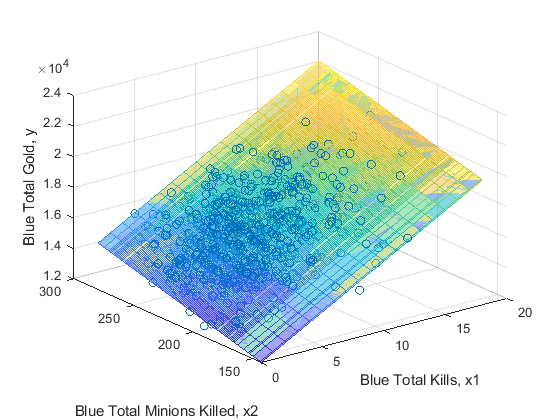

% Enter code for question 2 here
n = 750;
k = 2;

x = [ones(750, 1), x1, x2];
xt = transpose(x);
xtx = xt*x;
xty = xt*y;
inv_xtx = inv(xtx);
b_vals = inv_xtx * xty;

[X1, X2] = meshgrid(x1, x2);
y_reg = b_vals(1) + b_vals(2)*X1 + b_vals(3)*X2;
surf(X1, X2, y_reg, 'FaceAlpha', 0.5, "EdgeColor","interp");

hold on
scatter3(x1, x2, y);
xlabel('Blue Total Kills, x1');
ylabel('Blue Total Minions Killed, x2');
zlabel('Blue Total Gold, y');
hold off


b0 = b_vals(1)

b0 = 8.9035e+03

b1 = b_vals(2)

b1 = 451.6605

b2 = b_vals(3)

b2 = 22.1336

The value of b1 (or slope) is 451.6605 and the value of b2 (or slope) is 22.1336. As both of them are positive and as we can observe from the plot, we can say that both of them have a positive impact on the output y. That is, both b1 and b2 are directly proportional to y.

# QUESTION 3

% write your code here code
SSreg = 0;
SStot = 0;
yh = x*b_vals;

for i=1:n
    SSreg = SSreg + (yh(i) - mean(y))^2;
    SStot = SStot + (y(i) - mean(y))^2;
end

%SSreg2 = transpose(yh - mean(y, 1))*(yh - mean(y, 1));
%SStot2 = transpose(y - mean(y, 1))*(y - mean(y, 1));

R2 = SSreg/SStot

R2 = 0.8906

%R22 = SSreg2/SStot2

SSerr = transpose(y - yh)*(y - yh);
%SSerr2 = SStot - SSreg;

MSR = SSreg/k;
MSE = SSerr/(n-k-1);

Fobs = MSR/MSE

Fobs = 3.0406e+03

%Fobs2 = (SSreg/k)/(SSerr2/(n-k-1));
Fval = finv(1-0.05, k, n-k-1)

Fval = 3.0078


if(Fobs>Fval)
   disp('The null hypothesis has been rejected.')
else
   disp('The hypothesis has been accepted.')
end

The null hypothesis has been rejected.



pval = 1 - fcdf(Fobs, k, n-k-1)

pval = 0

%pval2 = 1 - cdf('F', Fobs, k, n-k-1)

The value for the coefficient of determination is 0.8906. That is, 89.06% of the total variation of the number of processed requests is explained by sizes of data sets only.

We know from theory that if the value of the coefficient of determination is lower than 0.2, we have a poor fit, while if it is greater than 0.8 it is a very good fit. As in this case we have a coefficient of determination of 0.8906, we have a very good fit for our data.

------------------------------------------------------------------------------------------------------------------------------------

Since we want to check if our model account significantly for the variability of our data, we will have the null hypothesis Ho: {Bi = 0, ∀i > 0} against the alternative hypothesis Ha: {∃i > 0 | Bi ≠ 0}.

As we have obtained an Fobs >>> Fval, we can therefore reject the null hypothesis, which means that the regression model is significative for alpha = 0.05.

The ANOVA F-test is always one-sided and right-tail because only large values of the F-statistic show a large portion of explained variation and the overall significance of the model.

------------------------------------------------------------------------------------------------------------------------------------

When Ho is true, the test statistic F has an F distribution with k numerator d.f. and n-k-1 denominator d.f. The test is upper-tailed, so the P-value is the area under the F_(k, n-k-1) curve to the right of f.

The P-value is the probability that a single observation from an *F* distribution with degrees of freedom will fall in the interval [0 *x*].

# QUESTION 4

% write your code here
s2 = MSE;
alpha = 0.05;
df = n-k-1;

CovBls = s2*inv_xtx;
s2b1 = CovBls(2, 2);
s2b2 = CovBls(3, 3);

tci = tinv(1-alpha/2, df)

tci = 1.9631


tobs1 = (b1-0)/(sqrt(s2b1))

tobs1 = 73.8028

if(abs(tobs1)>tci)
   disp('The hypothesis that x1 has an effect on y has been rejected.')
else
   disp('The hypothesis that x1 has an effect on y has been accepted.')
end

The hypothesis that x1 has an effect on y has been rejected.



pval1 = 2*(1-tcdf(abs(tobs1),df))

pval1 = 0


tobs2 = (b2-0)/(sqrt(s2b2))

tobs2 = 6.2004

if(abs(tobs2)>tci)
   disp('The hypothesis that x2 has an effect on y has been rejected.')
else
   disp('The hypothesis that x2 has an effect on y has been accepted.')
end

The hypothesis that x2 has an effect on y has been rejected.



pval2 = 2*(1-tcdf(abs(tobs2),df))

pval2 = 0.0034